# Two-Compartment Model

clc, clearvars, close all

% load dataset in csv format
dataset = 'FINAL_mrgsolve_simulation';

% load data into matrix
Subject3 = readmatrix(dataset)

Subject3 =     1.0000         0         0  500.0000         0         0         0   71.4286
    1.0000    0.1000         0  478.2920    8.7995    2.0949         0   68.3274
    1.0000    0.2000         0  457.5218   17.2095    4.0968         0   65.3603
    1.0000    0.3000         0  437.6501   25.2468    6.0097         0   62.5214
    1.0000    0.4000         0  418.6390   32.9277    7.8374         0   59.8056
    1.0000    0.5000         0  400.4521   40.2676    9.5835         0   57.2074
    1.0000    0.6000         0  383.0546   47.2812   11.2518         0   54.7221
    1.0000    0.7000         0  366.4130   53.9827   12.8455         0   52.3447
    1.0000    0.8000         0  350.4952   60.3858   14.3678         0   50.0707
    1.0000    0.9000         0  335.2704   66.5033   15.8220         0   47.8958


row_n = size(Subject3, 1);
inc = 0.1; % time increment of dataset

tf = 48; % set time domain

% TEST PLOT

% paramaters with placeholder values
k10 = 0; % elimination rate
k12 = 1; % kinetic constant, central to peripheral
k21 = 0.01; % kinetic constant, peripheral to central
C0 = 500; % initial amount injected into central compartment

k_matrix = [0.1387 0.01 0.001; 0.1387 2.043 0.001; 0.1387 0.2043 0.01373; 0.4 0.2043 0.01373; 0.01 0.1057 0.001; 0.01 0.1057 0.01373; 0.2713 0.1057 0.01373; 0.2713 0.3 0.01373; 0.01 0.01 0.00727; 0.01 0.2043 0.00727; 0.2713 0.2043 0.00727; 0.2713 0.2043 0.02; 0.01 0.1057 0.00727; 0.2713 0.1057 0.00727; 0.2713 0.3 0.00727; 0.2713 0.3 0.02]

k_matrix =     0.1387    0.0100    0.0010
    0.1387    2.0430    0.0010
    0.1387    0.2043    0.0137
    0.4000    0.2043    0.0137
    0.0100    0.1057    0.0010
    0.0100    0.1057    0.0137
    0.2713    0.1057    0.0137
    0.2713    0.3000    0.0137
    0.0100    0.0100    0.0073
    0.0100    0.2043    0.0073


output = zeros(16,6);

% implementation of runge kutta method to solve ODE
h = 0.1; % h=timestep
ASol_RK = zeros(tf+1,3); % initialize matrix to store solution for two compartments

% set initial conditions
row = 16

row = 16

x=h; % x value incrementing by h
    ASol_RK = zeros(tf+1, 3);
    ASol_RK(1,1) = 0; % first column (time)
    ASol_RK(1,2) = C0; % second column (central compartment)
    ASol_RK(1,3) = 0; % third column (peripheral compartment)
    k10 = k_matrix(row, 1);
    k12 = k_matrix(row, 2);
    k21 = k_matrix(row, 3);
    for i = 1:tf/h
        ASol_RK(i+1, 1) = x; % set time
        x = x + h; % increment time
    
        % central compartment
        j1 = -k10 * ASol_RK(i, 2) - k12 * ASol_RK(i, 2) + k21 * ASol_RK(i, 3);
        j2 = -k10 * (ASol_RK(i, 2)+j1*h/2) - k12 * (ASol_RK(i, 2)+j1*h/2) + k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = -k10 * (ASol_RK(i, 2)+j2*h/2) - k12 * (ASol_RK(i, 2)+j2*h/2) + k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = -k10 * (ASol_RK(i, 2)+j3*h) - k12 * (ASol_RK(i, 2)+j3*h) + k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 2) = ASol_RK(i, 2) + h/6*(j1+2*j2+2*j3+j4);
    
        % peripheral compartment
        j1 = k12 * ASol_RK(i, 2) - k21 * ASol_RK(i, 3);
        j2 = k12 * (ASol_RK(i, 2)+j1*h/2) - k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = k12 * (ASol_RK(i, 2)+j2*h/2) - k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = k12 * (ASol_RK(i, 2)+j3*h) - k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 3) = ASol_RK(i, 3) + h/6*(j1+2*j2+2*j3+j4);
    
        %ASol_Euler(i+1, 2) = ASol_Euler(i, 2) + (-k10 * ASol_Euler(i, 2) - k12 * ASol_Euler(i, 2) + k21 * ASol_Euler(i, 3))*h;
        %ASol_Euler(i+1, 3) = ASol_Euler(i, 3) + (k12 * ASol_Euler(i, 2) -
        %k21 * ASol_Euler(i, 3))*h;
    
    end
    ASol_RK(9, 2)

ans = 317.0898

    ASol_RK(41, 2)

ans = 56.8993

    ASol_RK(121, 2)

ans = 9.1266

    ASol_RK(9, 3)

ans = 99.7503

    ASol_RK(41, 3)

ans = 236.3965

    ASol_RK(121, 3)

ans = 243.4733

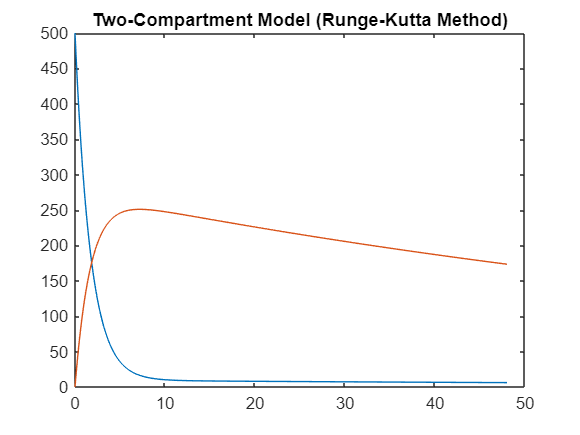


% plot solutions calculated by runge kutta algorithm on the same graph
plot(ASol_RK(:,1), ASol_RK(:, 2))
hold on
plot(ASol_RK(:,1), ASol_RK(:, 3))
title("Two-Compartment Model (Runge-Kutta Method)")
hold off

%{
% initial conditions
cond1 = A1(0) == C0;
cond2 = A2(0) == 0;
conds = [cond1; cond2];

% Compute Solutions
[A1Sol(t), A2Sol(t)] = dsolve(odes, conds);

% plot theoretical data (before fitting)
fplot(A1Sol,[0 tf]) 
hold on
fplot(A2Sol, [0 tf])
grid on
legend("A1","A2", Location = "best");
title('Concentration of Styrene in Blood and Andipose Over Time')
hold off

% plot experimental data points
scatter(Subject1(domain(1):domain(2),1), Subject1(domain(1):domain(2),2));

scatter(Subject2(domain(3):domain(4),1), Subject2(domain(3):domain(4),2));

hold off
%}
%{
% A1 as a function of experimental t values in set domain
y1 = zeros(n1, 1);
for n = 1:n1
    y1(n) = A1Sol(Subject1(domain(1)+n-1, 1)); % y1 theoretical conc.
end

% A2 as a function of experimental t values in set domain
y2 = zeros(n2, 1);
for n = 1:n2
    y2(n) = A2Sol(Subject2(domain(3)+n-1, 1)); % y2 theoretical conc.
end
%}
% Optimize RMSE (OLD)
%{
function [RMSE, A1Sol, A2Sol, RMSE_num1, RMSE_num2] = calculateRMSE(k10, k12, k21, n1, n2, domain, Subject1, Subject2, C0)
    %new first order system
    
    syms A1(t) A2(t)

    ode1 = diff(A1,t) == -k10 * A1 - k12 * A1 + k21 * A2;
    ode2 = diff(A2,t) == k12 * A1 - k21 * A2;
    odes = [ode1; ode2]; 

    % initial conditions
    cond1 = A1(0) == C0;
    cond2 = A2(0) == 0;
    conds = [cond1; cond2];

    % Compute Solutions
    [A1Sol(t), A2Sol(t)] = dsolve(odes, conds);
    

    % A1 as a function of experimental t values in set domain
    y1 = zeros(n1, 1);
    for n = 1:n1
        y1(n) = A1Sol(Subject1(domain(1)+n-1, 1)); % y1 theoretical conc.
    end

    % A2 as a function of experimental t values in set domain
    y2 = zeros(n2, 1);
    for n = 1:n2
        y2(n) = A2Sol(Subject2(domain(3)+n-1, 1)); % y2 theoretical conc.
    end

    RMSE_num1 = 0;
    RMSE_num2 = 0;
    for n = 1:n1
        RMSE_num1 = RMSE_num1 + (abs(Subject1(domain(1)+n-1, 2)-y1(n)))^2;
    end
    
    for n = 1:n2
        RMSE_num2 = RMSE_num2 + (abs(Subject2(domain(3)+n-1, 2)-y2(n)))^2;
    end
    
    RMSE = sqrt((RMSE_num1+RMSE_num2)/(n1+n2));
end

%}

% ACTUAL IMPLEMENTATION
h = 0.1; % set increment
% Function for optimizing solution with Runge-Kutta according to parameters
function [MSE, RMSE, ASol_RK, RMSE_num1, RMSE_num2, MSE_real, RMSE_real, RMSE_num1_real, RMSE_num2_real] = calculateRungeKutta(k10, k12, k21, Subject3, C0, tf, h, inc)
    
    ASol_RK = zeros(tf/h+1, 3); % initialize matrix of solutions

    % set initial conditions
    ASol_RK(1,1) = 0; % first column (time)
    ASol_RK(1,2) = C0; % second column (central compartment amount)
    ASol_RK(1,3) = 0; % third column (peripheral compartment amount)
    x=h; % x value incrementing by h
    for i = 1:tf/h
        ASol_RK(i+1, 1) = x; % set time
        x = x + h; % increment time

        % calculate central compartment
        j1 = -k10 * ASol_RK(i, 2) - k12 * ASol_RK(i, 2) + k21 * ASol_RK(i, 3);
        j2 = -k10 * (ASol_RK(i, 2) + j1*h/2) - k12 * (ASol_RK(i, 2) + j1*h/2) + k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = -k10 * (ASol_RK(i, 2) + j2*h/2) - k12 * (ASol_RK(i, 2) + j2*h/2) + k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = -k10 * (ASol_RK(i, 2)+j3*h) - k12 * (ASol_RK(i, 2)+j3*h) + k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 2) = ASol_RK(i, 2) + h/6*(j1+2*j2+2*j3+j4);

        % calculate peripheral compartment
        j1 = k12 * ASol_RK(i, 2) - k21 * ASol_RK(i, 3);
        j2 = k12 * (ASol_RK(i, 2)+j1*h/2) - k21 * (ASol_RK(i, 3)+j1*h/2);
        j3 = k12 * (ASol_RK(i, 2)+j2*h/2) - k21 * (ASol_RK(i, 3)+j2*h/2);
        j4 = k12 * (ASol_RK(i, 2)+j3*h) - k21 * (ASol_RK(i, 3)+j3*h);
        ASol_RK(i+1, 3) = ASol_RK(i, 3) + h/6*(j1+2*j2+2*j3+j4);
    end

    row_n = size(Subject3, 1);
    % calculate expected values for central compartment
    y1 = zeros(tf, 1);
    for n = 1:row_n
        %y1(n) = ASol_RK(fix(Subject3(n, 2)*(1/h)+1), 2); 
        y1(n) = ASol_RK(n, 2);
    end

    % calculate expected values for peripheral compartment
    y2 = zeros(tf, 1);
    for n = 1:row_n
        %y2(n) = ASol_RK(fix(Subject3(n, 2)*(1/h)+1), 3); 
        y2(n) = ASol_RK(n, 3);
    end

    % calculate MSE and RMSE, only first 80% of datapoints for training
    % initialize SSE for error calculations (central and peripheral compartment)
    RMSE_num1 = 0;
    RMSE_num2 = 0;

    % calculate SSE for central compartment
    for n = 1:round(0.8*(tf/h + 1))
        RMSE_num1 = RMSE_num1 + (abs(Subject3(n, 4)-y1(n)))^2;
        %RMSE_num1 = RMSE_num1 + (abs(Subject3(1 + (n-1)*h/inc, 4)-y1(n)))^2;
    end
    % calculate SSE for peripheral compartment
    for n = 1:round(0.8*(tf/h + 1))
        RMSE_num2 = RMSE_num2 + (abs(Subject3(n, 5)-y2(n)))^2;
    end
    
    % calculate MSE and RMSE for compartments
    MSE = (RMSE_num1 + RMSE_num2)/(2*round(0.8*(tf/h + 1)));
    RMSE = sqrt((RMSE_num1 + RMSE_num2)/(2*round(0.8*(tf/h + 1))));


    % calculate MSE and RMSE, including unfitted data points
    RMSE_num1_real = 0;
    RMSE_num2_real = 0;

    % calculate SSE for central compartment
    for n = round(0.8*(tf/h + 1)) + 1:tf/h + 1
        RMSE_num1_real = RMSE_num1_real + (abs(Subject3(n, 4)-y1(n)))^2;
    end
    % calculate SSE for peripheral compartment
    for n = round(0.8*(tf/h + 1)) + 1:tf/h + 1
        RMSE_num2_real = RMSE_num2_real + (abs(Subject3(n, 5)-y2(n)))^2;
    end

    % calculate real MSE and RMSE for compartments
    MSE_real = (RMSE_num1_real + RMSE_num2_real)/(2*(tf/h + 1 - round(0.8*(tf/h + 1))));
    RMSE_real = sqrt((RMSE_num1_real + RMSE_num2_real)/(2*(tf/h + 1 - round(0.8*(tf/h + 1)))));
end


% data fitting based on experimental data
RMSE_min = Inf;

% set range of parameters being tested
C0 = 500;
k10_t = linspace(0.01, 0.5, 20);
k12_t = linspace(0.01, 0.5, 20);
k21_t = linspace(0.004, 0.01, 30);

% loop through parameters, calling Runge-Kutta function each time
for k1 = k10_t 
    for k2 = k12_t
        for k3 = k21_t
            [MSE, RMSE, ASol_temp, RMSE_num1, RMSE_num2, MSE_real, RMSE_real, RMSE_num1_real, RMSE_num2_real] = calculateRungeKutta(k1, k2, k3, Subject3, C0, tf, h, inc);
            if RMSE < RMSE_min
                RMSE_min = RMSE; % save minimum RMSE
                MSE_min = MSE;
                MSE_real_min = MSE_real;
                RMSE_real_min = RMSE_real;
                A1Sol_best = ASol_temp(:,2); % save central compartment solution
                A2Sol_best = ASol_temp(:,3); % save peripheral compartment solution

                % save parameters
                k10 = k1;
                k12 = k2;
                k21 = k3;
                
                % save SSE (both compartments)
                SSE = RMSE_num1_real + RMSE_num2_real;
            end
        end 
    end 
end 

% Parameter and Error Results
MSE_min

MSE_min = 6.0011

RMSE_min

RMSE_min = 2.4497

MSE_real_min

MSE_real_min = 4.6532

RMSE_real_min

RMSE_real_min = 2.1571

k10

k10 = 0.2679

k12

k12 = 0.1647

k21

k21 = 0.0052

SSE

SSE = 893.4103

n = round(0.2*(tf/h + 1));
% Akaike Information Criterion (AICc) and Bayesian Information Criterion (BIC) 
AICc = (2*n)*log(SSE/(2*n)) + 2*3 + 2*3*(3+1)/(2*n-3-1) + (2*n)*log(2*pi) + 2*n

AICc = 846.2098

BIC = (2*n)*log(SSE/2*n) + 3*log(2*n) + (2*n)*log(2*pi) + (2*n)

BIC = 2.6086e+03

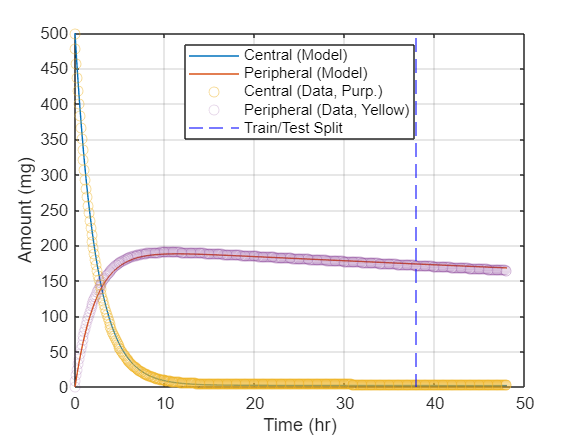

 
% plot fitted model
%{
fplot(A1Sol_best,[0 tf]) 
hold on
fplot(A2Sol_best, [0 tf])
grid on
legend("A1","A2", Location = "best");
xlabel("Time (hr)")
ylabel("Concentration (ug/g)")
title('Two-Compartment Model Fitted to Data')

% plot experimental data points on fitted data
scatter(Subject1(domain(1):domain(2),1), Subject1(domain(1):domain(2),2));

scatter(Subject2(domain(3):domain(4),1), Subject2(domain(3):domain(4),2));

hold off
%}

% Plot model fitted by Runge-Kutta
t = linspace(0, tf, tf/h+1);
plot(t, A1Sol_best) 
hold on
plot(t, A2Sol_best)
grid on
xlabel("Time (hr)")
ylabel("Amount (mg)")
%title('Fitted Two-Compartment Model (Runge)')
%{
% plot experimental data points on fitted data
scatter(Subject1(domain(1):domain(2),1), Subject1(domain(1):domain(2),2));

scatter(Subject2(domain(3):domain(4),1), Subject2(domain(3):domain(4),2));

hold off
%}

% Plot experimental data on top of model
scatter(Subject3(:,2), Subject3(:,4), "MarkerEdgeAlpha", 0.5);
scatter(Subject3(:,2), Subject3(:,5), "MarkerEdgeAlpha", 0.2);
xline(round(0.8*tf), color = "blue", lineStyle = "--")
legend("Central (Model)","Peripheral (Model)", "Central (Data, Purp.)", "Peripheral (Data, Yellow)", "Train/Test Split", Location = "best");
hold off

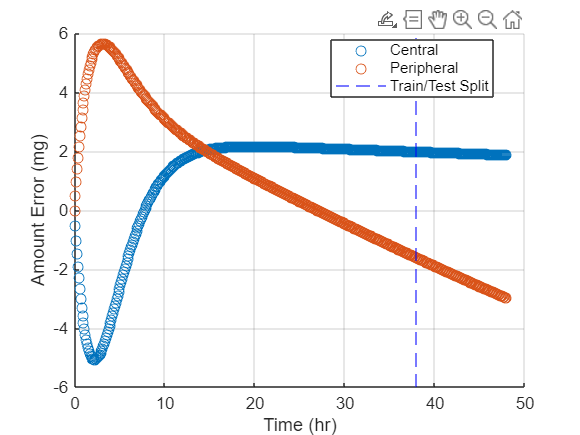


%{
% calculate and plot residuals
res1 = zeros(n1, 2);
for i = 1:n1
    res1(i, 1) = Subject1(domain(1)+i-1, 1);
    res1(i, 2) = Subject1(domain(1)+i-1, 2)-y1(i);
end
res1
scatter(res1(:,1), res1(:,2))
hold on
res1_p = polyfit(res1(:, 1), res1(:, 2), 1)
y_res1 = polyval(res1_p, Subject1(domain(1):domain(2), 1));
plot(Subject1(domain(1):domain(2)), y_res1)
legend("Error", "y=" + res1_p(1) + "x+" + res1_p(2))
title("Residual Plot of Two-Compartment Model")
%}

% Plot residuals
Residuals = zeros(tf+1,3);
for i = 1:tf/h + 1
    %Residuals(i, 1) = Subject3(1 + (i-1)*h/inc, 2);
    Residuals(i, 1) = Subject3(i, 2);
    Residuals(i, 2) = Subject3(i, 4) - A1Sol_best(i);
    Residuals(i, 3) = Subject3(i, 5) - A2Sol_best(i);
end

scatter(Residuals(:, 1), Residuals(:, 2))
hold on
grid on
scatter(Residuals(:, 1), Residuals(:, 3))
xline(round(0.8*tf), color = "blue", lineStyle = "--")
legend("Central", "Peripheral", "Train/Test Split", Location = "best")
%title("Residuals of Two-Compartment Model")
xlabel("Time (hr)")
ylabel("Amount Error (mg)")